# Marstorp and Witter (1999)

Marstorp, H., & Witter, E. (1999). Extractable dsDNA and product formation as measures of microbial growth in soil upon substrate addition. *Soil Biology and Biochemistry*, *31*(10), 1443–1453. [https://doi.org/10.1016/S0038-0717(99)00065-6](https://doi.org/10.1016/S0038-0717(99)00065-6)

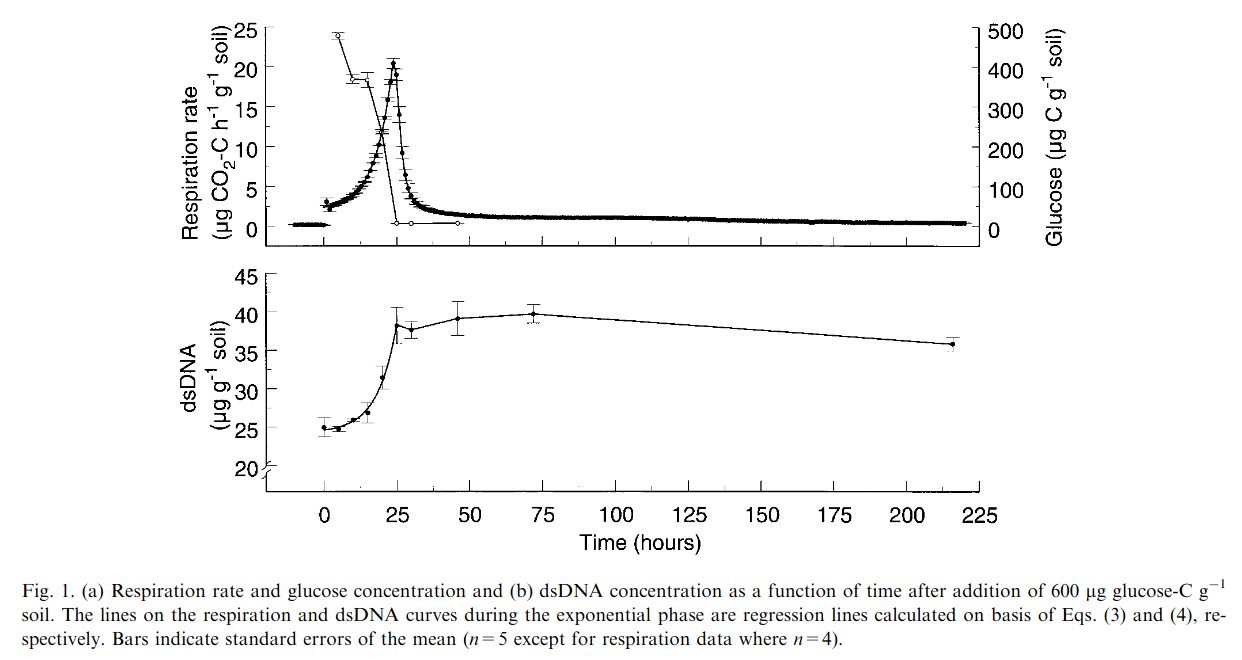

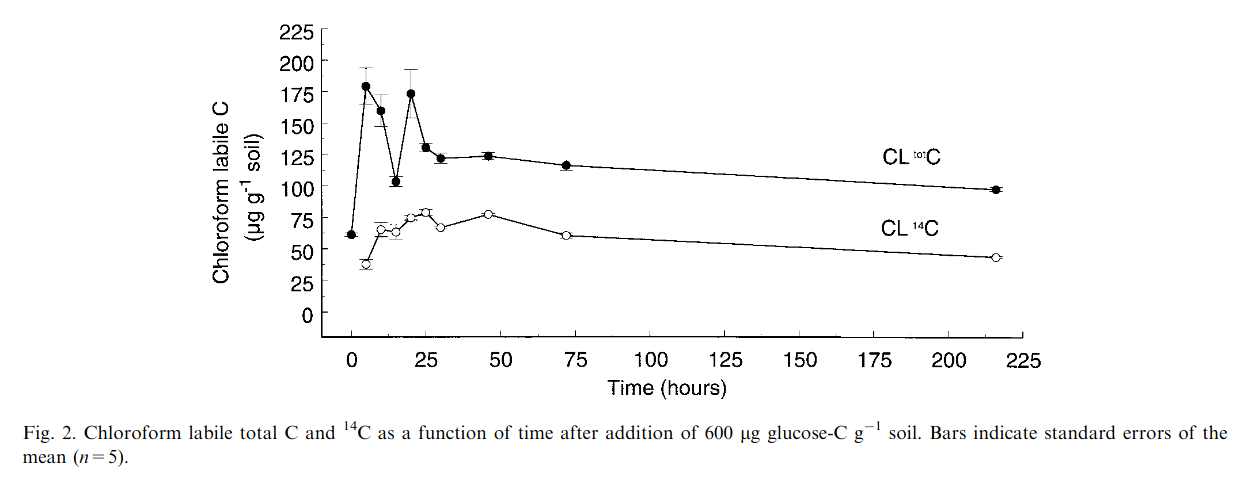

## Using DEB model to explain the difference between Flush and dsDNA dynamic

Data have been extracted from Figs. 1 and two using WebPlotDigitizer (https://apps.automeris.io/wpd/).

%Visualazing the data
tExperimental = Marstorp1999.Time;
Flush = Marstorp1999.Cmic12 + Marstorp1999.Cmic14;
DNA = Marstorp1999.DNA;
CO2 = Marstorp1999.CO212cumul;
R = Marstorp1999.CO212;
S = Marstorp1999.S;

plot(tExperimental, Flush./Flush(1), 'r--o');

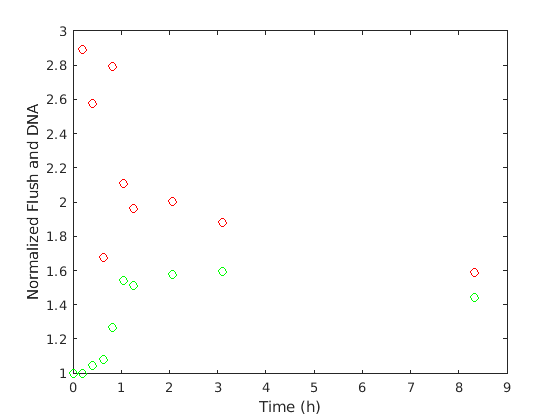

hold on
plot(tExperimental, DNA./DNA(1), 'g--o');
hold off
ylabel("Normalized Flush and DNA")
xlabel("Time (h)")

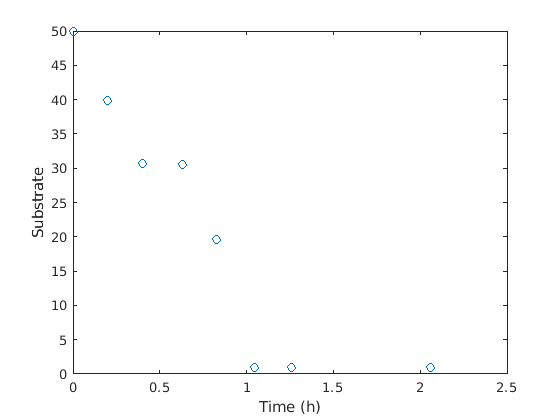

plot(tExperimental, S, 'o');
ylabel("Substrate")
xlabel("Time (h)")

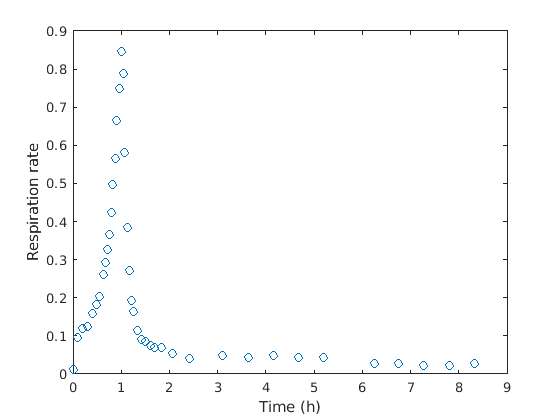

plot(tExperimental, R, 'o');
ylabel("Respiration rate")
xlabel("Time (h)")

# Parameters calibration

Parameters of DEB model are calibrated using fmincon runing from 2000 random initial sets of points using MultiStart function. The optimization is defined in DEBsearch defined below. Objective function minimizes weighted residual sum of squares (see details below). All measured variables are weighted by its standard deviation.  

%Define parameters to be optimized
%%Initial parameters guess
yA = [0.8, 0.05, 1]; Km = [50, 10, 10000]; v = [0.1, 1e-3, 20]; m = [0.01, 1e-12, 0.1]; 
g = [0.8, 0.1, 3]; ce = [4, 0.01, 10];  nX1 = [0.3, 0.1, 1];
%cX1 = 4; Km = 50; k = 1e-3;
x0 = [yA(1) Km(1) v(1) m(1) g(1) ce(1) nX1(1)];
lb = [yA(2) Km(3) v(2) m(2) g(2) ce(2) nX1(2)];
ub = [yA(3) Km(3) v(3) m(3) g(3) ce(3) nX1(3)];

%Call python to return value of objective function
pyenv

ans =   PythonEnvironment with properties:

          Version: "2.7"
       Executable: "/usr/bin/python"
          Library: ""
             Home: "/usr"
           Status: NotLoaded
    ExecutionMode: InProcess



if count(py.sys.path,'') == 0
    insert(py.sys.path,int32(0),'');
end

Unable to resolve the name py.sys.path.

## **Optimization**

warning('off');
DEBpars = DEBSearch(x0, lb, ub, tspan, S0, Flush0, DNA0, tExperimental, dataExperimental, weights);

MultiStart completed the runs from all start points.

All 4999 local solver runs converged with a positive local solver exit flag.


## Vizualization of the model fit

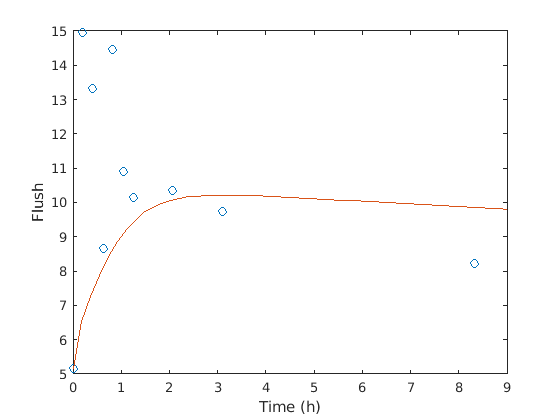

%Vizualization
%%Defining Y0
ce = DEBpars(6);
cX1 = 4;
nX1 = DEBpars(7);
iX1 = DNA0/(Flush0/nX1*(4/ce));
MX1 = ce/cX1;
   
%e_0 = (Flush0/DNA0)*(iX1/cX1) - (nX1/cX1);
X1_0 = Flush0/nX1*(4/ce);
        
Y0 = [S0; 0; X1_0; 0];

tfit = linspace(0, 9, 50);

%obtain the Model simulation
simOut = ode45(@(t,y)DEBODE(t,y,DEBpars),tfit,Y0);
%simData is a matrix with 4 rows representing 4 pools (S, e, X1 and CO2)
predsDEB = deval(simOut, tfit);
%Convert X1 and e to B, DNA and Flush - adding rows 5 to 7
%%B
predsDEB(5, :) = (MX1 + ce.*predsDEB(2, :)).*predsDEB(3, :);
%%DNA
predsDEB(6, :) = (iX1/cX1)./(1/cX1 + predsDEB(2, :)).*predsDEB(5, :);
%Flush
predsDEB(7, :) = ((nX1/cX1) + predsDEB(2, :))./(1/cX1 + predsDEB(2, :)).*predsDEB(5, :);

plot(tExperimental, Flush, 'o');
hold on
plot(tfit', predsDEB(7, :)', "-");
hold off
ylabel("Flush")
xlabel("Time (h)")

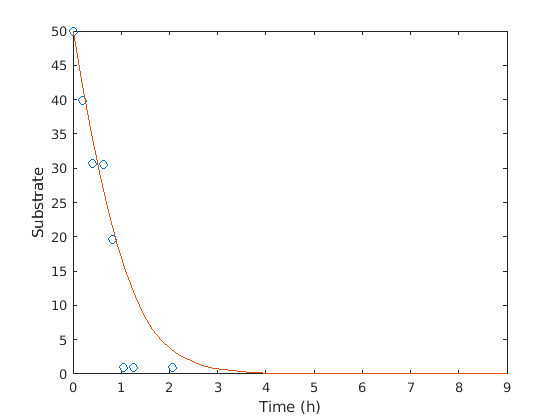

plot(tExperimental, S, 'o');
hold on
plot(tfit', predsDEB(1, :)', "-");
hold off
ylabel("Substrate")
xlabel("Time (h)")

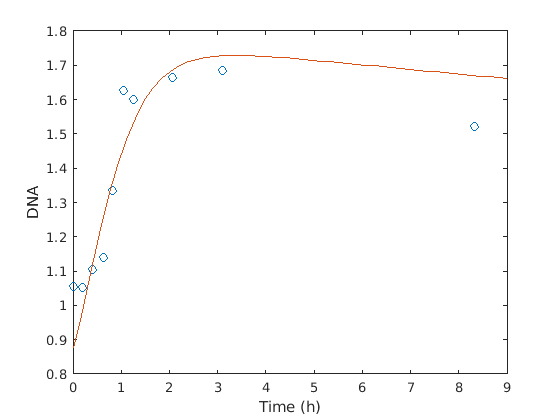

plot(tExperimental, DNA, 'o');
hold on
plot(tfit', predsDEB(6, :)', "-");
hold off
ylabel("DNA")
xlabel("Time (h)")

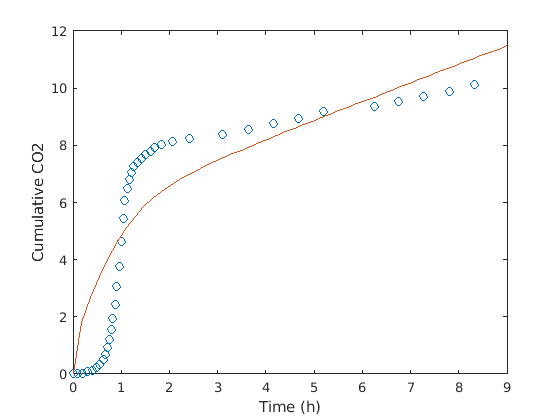


plot(tExperimental, Marstorp1999.CO212cumul, 'o');
hold on
plot(tfit', predsDEB(4, :)', "-");
hold off
ylabel("Cumulative CO2")
xlabel("Time (h)")

# Dynamic Energy Budget (DEB) theory model 

DEB model is shown on the picture below.

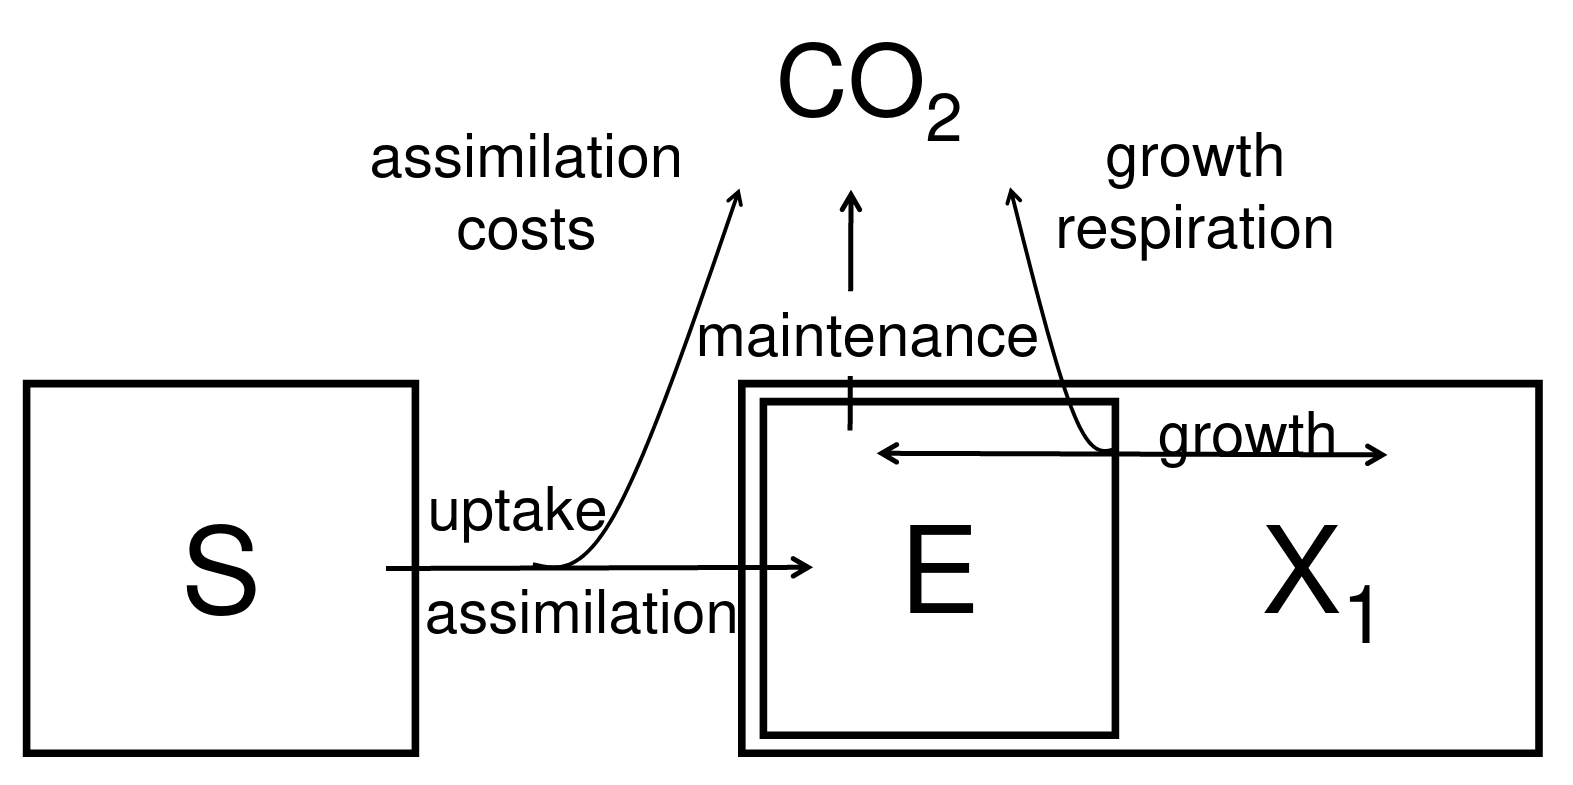

The model consists of 4 pools - Organic substrate (S), structural biomass of microorganisms ($X_{1}$), energy reserves of microorganisms (E) and $CO_{2}$. Substrate (in C-moles) is taken up and assimilated into pool of reserves (energy units) with certain efficiency. Energy is dissipated to maintain $X_{1}$ and grow. Maintenance has priority over growth. Growth is realized only when enough energy is available and it is associated with respiratory looses. When E is too small to cover maintenance costs, $X_{1}$ is used instead. $X_{1}$ is dying at constant rate.

### [Volume-specific] fluxes

function dYdt = DEBODE(t, Y, p)
    %Pools
    S = Y(1);   e = Y(2);    X1 = Y(3);    CO2 = Y(4);
    
    %Parameters
    Imax = p(3)*p(6)/p(1);    
    Km = p(2);    
    v = p(3);    
    m = p(4);     
    g = p(5);     
    %k = p(6);
    ce = p(6);    
    MX1 = ce/4;
    
    %Scaling function
    f = S/(Km + S);
    %Fluxes
    uptake = Imax*X1*f;
    growth = (v*e-m*g)/(e+g); %specific growth rate
    %death = k*X1;   
        
    %Derivatives
    dSdt = -uptake;
    dedt = v*(f - e);
    dX1dt = X1*growth; %- death;
    dCO2dt = uptake*(1 - p(1)) + (ce*(X1*e*(v-growth)) - growth*X1*MX1);
        
    dYdt = [dSdt; dedt; dX1dt; dCO2dt];
end

### {Surface-specific} and [Volume-specific] fluxes

%This is the DEB model with 4 pools
function dYdt = DEBSV(t, Y, p)
    %Pools
    S = Y(1);    e = Y(2);    X1 = Y(3);    CO2 = Y(4);
    
    %Parameters
    Imax = p(3)*p(6)/p(1);    
    Km = p(2);    
    v = p(3);    
    m = p(4);     
    g = p(5);     
    %k = p(6);
    ce = p(6);    
    MX1 = ce/4;
    
    %Scaling function
    f = S/(Km + S);
    %Fluxes
    uptake = Imax*X1^(2/3)*f;
    growth = (v*X1^(-1/3)*e-m*g)/(e+g); %specific growth rate
    %death = k*X1;   
        
    %Derivatives
    dSdt = -uptake;
    dedt = v*X1^(-1/3)*(f - e);
    dX1dt = X1*growth; %- death;
    dCO2dt = uptake*(1 - p(1)) + (ce*(X1*e*(v*X1^(-1/3)-growth)) - growth*X1*MX1);
    
    dYdt = [dSdt; dedt; dX1dt; dCO2dt];
    end

# Objective function

DEB model has to 10 parameters to optimize:


$$[I_{MAX}]~or~\left\{I_{MAX}\right\},~K,~v,~m.~g,~k,~c_{e} ,[M_{X_{1}}],~n_{X_{1}}~ and~i_{X_{1}} $$


Objective function optimizes combination of 7 of these parameters ($K,~v,~m.,~k,~c_{e},~n_{X_{1}}~ and~i_{X_{1}} $) explicitely and 3 are defined indirectly to avoid negative $CO_{2}$ fluxes and increase the parameters meaning clarity. The 3 converted parameters are:

**Assimilation yield (**$y_{A}$**):**


$$y_A =\frac{v*c_e }{I_{\textrm{MAX}} }$$


whose value is between 0.05 and 1, and which defines value of the parameter $[I_{MAX}]~or~\left\{I_{MAX}\right\}$:


$$I_{\textrm{MAX}} =\frac{v*c_e }{y_A }$$


**Growth yield (**$y_{G}$**):**

$y_G =\frac{1}{1+g}$ so $g=\frac{1}{y_G }-1$

Similar as $y_{A}$, $y_{G}$ must be between 0.05 and 1.

**Normalized structural volume-to-molar conversion factor (**$c_{X_{1}}$**):**

$c_{X_1 } =\frac{c_e }{\left\lbrack M_{X_1 } \right\rbrack }$ so $\left\lbrack M_{X_1 } \right\rbrack =\frac{c_e }{c_{X_1 } }$

According to Hanegraaf and Muller (2001), $c_{X_1 } =4$. To increase the model flexibility, the parameter can be within 1 and 10.

Parameters $n_{X_{1}}~ and~i_{X_{1}} $ convert microbial biomass ($B$) to measured DNA and Flush concentration.

#### 1. Flush concentration


$$\textrm{Flush}=k_{\textrm{ec}} *B=k_{\textrm{ec}} *\left(\left\lbrack M_{X_1 } \right\rbrack +c_e *e\right)*X_1$$


where $k_{\textrm{ec}}$ is defined as:


$$k_{\textrm{ec}} =\frac{n_{X_1 } *\left\lbrack M_{X_1 } \right\rbrack +1*c_e *e}{\left\lbrack M_{X_1 } \right\rbrack +c_e *e}$$


It is assumed that $\left\lbrack M_{X_1 } \right\rbrack =\frac{c_e }{c_{X_1 } }$ so the equation simplifies to:


$$k_{\textrm{ec}} =\frac{n_{X_1 } /c_{X_1 } +e}{1/c_{X_1 } +e}$$


#### 2. DNA concentration


$$\textrm{DNA}=k_{\textrm{DNA}} *B$$


where $k_{\textrm{DNA}}$ is defined as:


$$k_{\textrm{DNA}} =\frac{i_{X_1 } *\left\lbrack M_{X_1 } \right\rbrack +0*c_e *e}{\left\lbrack M_{X_1 } \right\rbrack +c_e *e}=$$

$$\frac{i_{X_1 } /c_{X_1 } }{1/c_{X_1 } +e}$$


#### 3. Intial $X_{1}$ and $e$

Parameters $n_{X_{1}},~and~c_{e}$ and measured initial DNA and Flush concentrations are used to define intial $X_{1}$ ($X_1 \left(0\right)$), $e$ ($e\left(0\right)$) and $i_{X_{1}}$as follows:


$$e\left(0\right)=0$$



$$X_1 \left(0\right)=\frac{\textrm{Flush}}{k_{\textrm{ec}} }*\frac{c_{X_1 } }{c_e }=\textrm{Flush}*1/\frac{n_{X_1 } /c_{X_1 } +0}{1/c_{X_1 } +0}*\frac{c_{X_1 } }{c_e }=\frac{\textrm{Flush}}{n_{X_1 } }*\frac{c_{X_1 } }{c_e }$$


$X_1 \left(0\right)=\textrm{DNA}/\frac{i_{X_1 } /c_{X_1 } }{1/c_{X_1 } +0}\;$ so $i_{X_1 } =\frac{\textrm{DNA}}{X_1 \left(0\right)}$

%Objective function
function DEBPars = DEBSearch(x0, lb, ub, tspan, S0, Flush0, DNA0, tExperimental, dataExperimental, weights)

%DEBPars = simulannealbnd(@ObjectiveFunction, x0, lb, ub);
%DEBPars = particleswarm(@ObjectiveFunction,7,lb,ub);
%

ms = MultiStart("StartPointsToRun",'bounds');
problem = createOptimProblem('fmincon','x0',x0, 'objective', @ObjectiveFunction,'lb',lb,'ub',ub);
DEBPars = run(ms,problem, 5000);
%DEBPars = patternsearch(@ObjectiveFunction,pinit);

    function out = ObjectiveFunction(x)
        %define initial conditions
        %e_0 = (Flush0/DNA0)*(x(7)*0.25) - (0.25*x(6));
        X1_0 = Flush0/x(7)*(4/x(6));
        x(end+1) = DNA0/X1_0;
        
        Y0 = [S0; 0; X1_0; 0];

        %obtain the Model simulation
        %options = odeset('RelTol',1e-2,'AbsTol',1e-2);
        simOut = ode45(@(t,y)DEBODE(t,y,x),tspan,Y0);
        simData = deval(simOut, tExperimental);
        
        %Convert X1 and e to B, DNA and Flush - adding rows 5 to 7
        %%B
        simData(5, :) = (0.25 + simData(2, :)).*simData(3, :).*x(6);
        %%DNA
        simData(6, :) = (0.25*x(8))./(0.25 + simData(2, :)).*simData(5, :);
        %Flush
        simData(7, :) = ((0.25*x(7)) + simData(2, :))./(0.25 + simData(2, :)).*simData(5, :);
        
        %Select only measured variables S, CO2, Flush and DNA 
        simData = simData([1, 4, 6, 7], :);

        %sum of weighted square differencess between the simulations and observations
        out = nansum(((simData - dataExperimental)./weights).^2, 'all');
    
    end
end